# Visualize Pressure Data Using a Filled Contour Plot

`contourf` creates a filled contour plot containing the isolines of matrix `Z`, where `Z` contains height values on the *x*-*y* plane.

### Create Data

Use a pressure helper function to generate data representing pressure in air flow around a circular cylinder.

[r,theta,x,y,streamline,pressure] = flowAroundCylinder();

### Basic Contour Plot

Visualize the air pressure in the flow around a circular cylinder using `contourf`.

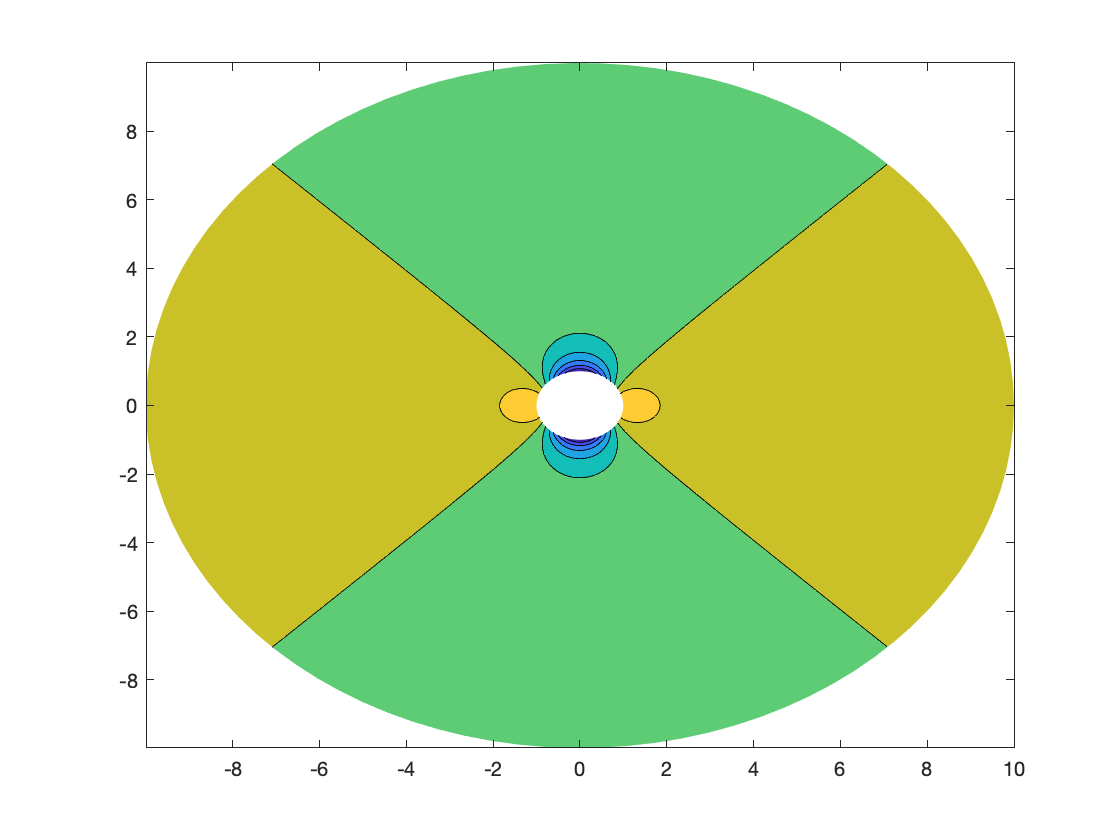

contourf(x,y,pressure);

## Customization

### Customize Contour Levels

Specify the number of contour levels as a 4th argument to `contourf`. This can increase the number of contour lines, and help improve the visualization. Specify the *LineWidth* of the contour lines using a Name, Value pair argument.

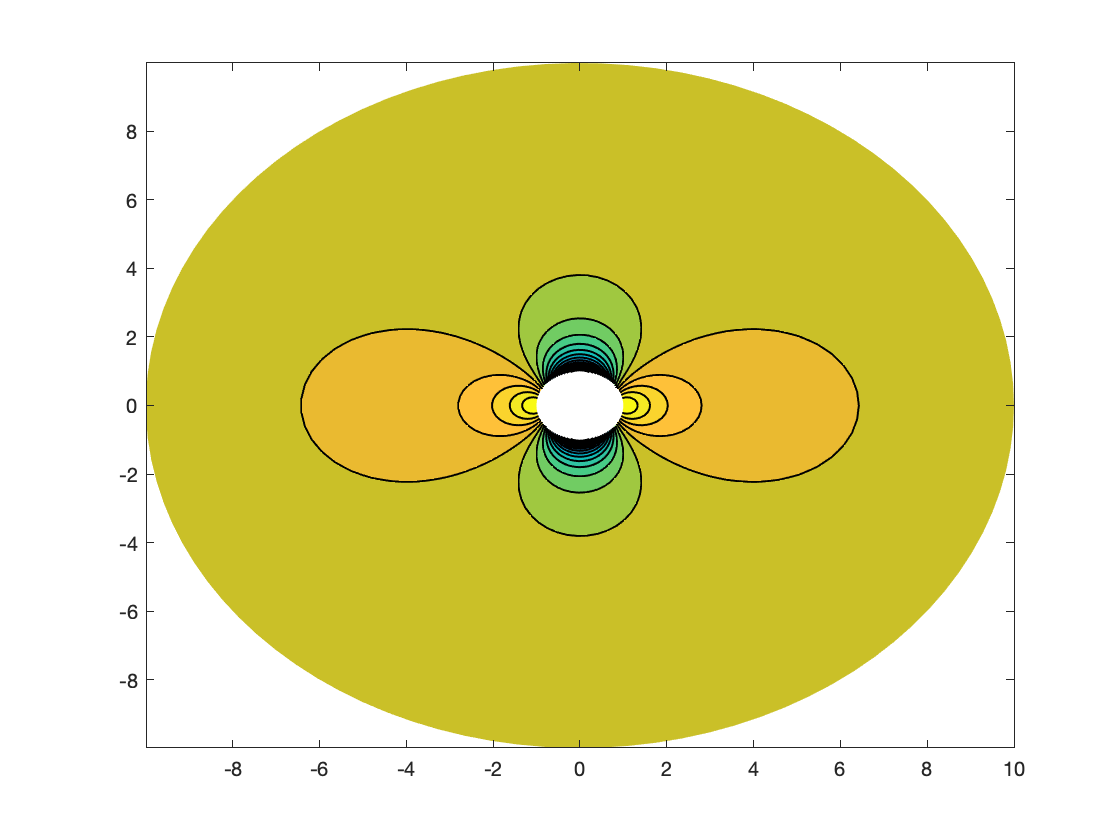

contourLevels = 20; 
LineWidth = 1; 

[~,c] = contourf(x,y,pressure,...
    contourLevels,...              % Specify a scalar integer number of contour levels
    "LineWidth",LineWidth);        % Specify the contour line width

### Customize Axes and Add Cylinder to Plot

Set axes limits and plot the cylinder using the `circle` helper function to improve the visualization. Add labels and a title to the axes. Customize label fonts using the `set` function.

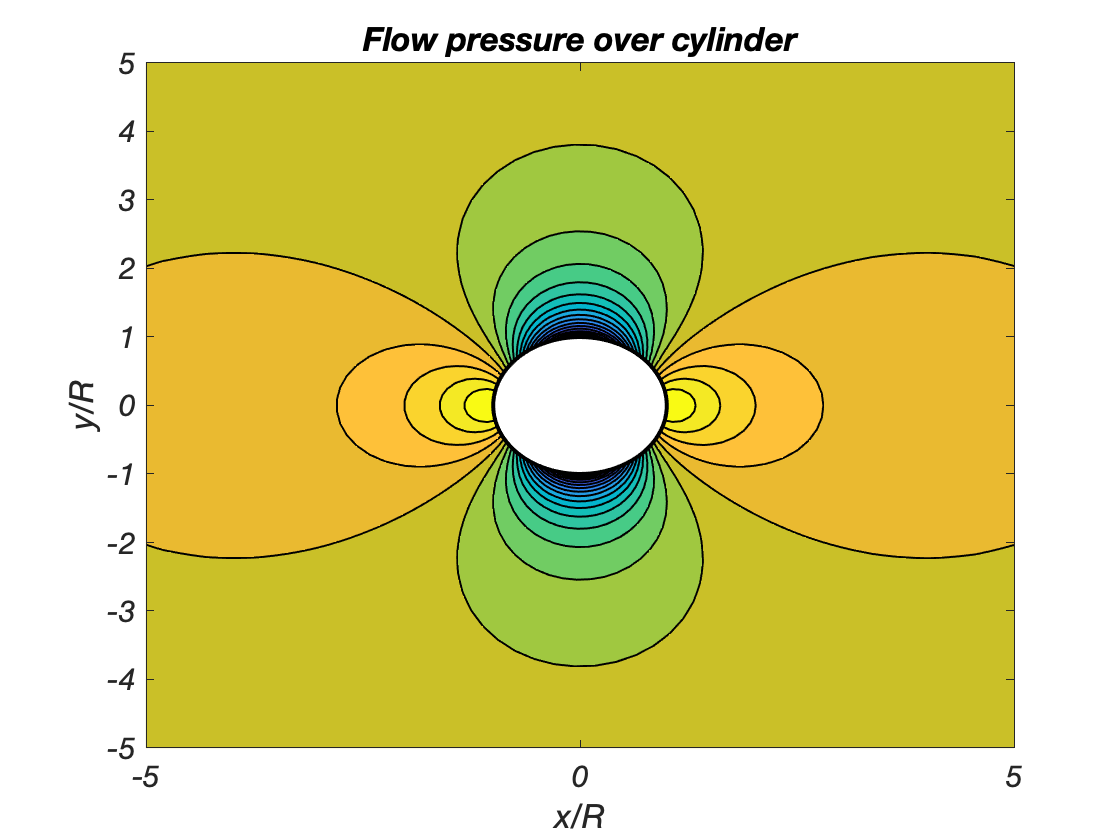

axis([-5, 5,...     % x-axis limits 
      -5, 5]);      % y-axis limits 
circle(0,0,1);      % Call helper function to plot circle

xlabel("x/R")
ylabel("y/R")
title("Flow pressure over cylinder")

set(gca,...
    "FontSize",15,...           % Set font size
    "FontAngle","italic");      % Italicize font

### Change Chart Colormap and Add Colorbar

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. Display a colorbar and add labels to it.

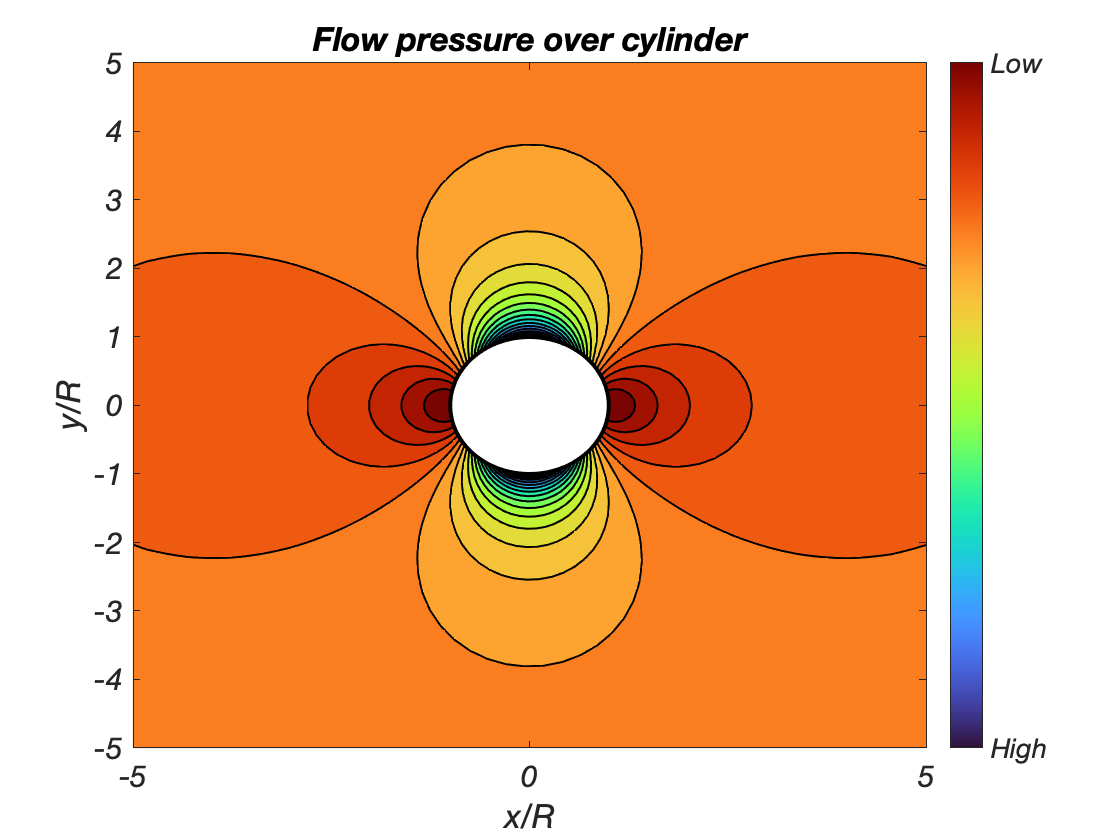

colormap("turbo");    % Specify a colormap to use in the contourf plot
cb = colorbar;                  
cb.Ticks = cb.Limits;                    
cb.TickLabels = ["High" "Low"];  % Specify labels for colorbar

## **Additional Information**

### **Get All Contour Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a contour, uncomment the following code. View or modify these properties using dot notation.

% get(c)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[contourf](https://www.mathworks.com/help/matlab/ref/contourf.html?searchHighlight=contourf&s_tid=srchtitle)

### Helper Functions

This function creates data representing streamlines & static pressure contours of an inviscid, incompressible, irrotational flow around a cylinder of any radius.

function [r,theta,x,y,streamline,pressure] = flowAroundCylinder()
V_i = 1000;
a = 1;
theta = linspace(0,2*pi,100); 
rr = linspace(a,10*a,100);        
[t,r] = meshgrid(theta,rr);                        % create meshgrid in two dimensions
[x,y] = pol2cart(t,r);                             % converts polar to cartesian coordinates
streamline = V_i.*sin(t).*r.*(1-(a^2./(r.^2)));      % Creation of the streamline function
pressure = 2*(a.^2./r.^2).*cos(2.*t)-(a.^4./r.^4); % static pressure around the cylinder
end

This function returns the handle for a circle plotted on the current axes.

function h = circle(x,y,r)
hold on
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit,"-k","LineWidth",2);
hold off
end